# Chapter 7 - Some Optimization Problems Solved w/ Matlab

## Section 1 - Computational Approach to Obtaining Optimal Sets of Parameter Values 

clear all; clc

This section will go over how to obtain optimal sets of parameter values of control systems to satisfy transient-response specifications. 

## 7-1 Example the unit-step response for varied K and a values

Consider two control systems: (1) PID controller and (2) Simplified PID controller. 

The TF of the PID is given by : $G_c \left(s\right)=K_p \left(1+\text{ }\frac{1}{T_i s}+T_d s\right)=\text{ }\frac{K\left(s+\alpha \right)\left(s+\beta \right)}{s}$. Typically, we choose $\alpha =\text{ }\beta$ to simplify the equations and reduce the number of variables from 3 to 2. The goal is to find the best combination of K and a such that the closed-loop system is underdamped and the max overshoot in a unit-step response is less that 15% but greater than 10%. 

To solve this in Matlab we need to: 

- Specify the region to search for appropriate K and a. If solution does not exist in the region, need to expand it. (some problems there is no solution)

- Write code that will find combo of K and a that will satisfy criteria for unit-step response

- Note: the gain, K, should not be too large 

Select step sizes to be 0.2 for K, and 0.1 for a and select regions to be 3<K<5 and 0.1<a<3.

% Nested loop to step through K and a values
t = 0:0.01: 8; 

for K = 3:0.2:5;
    for a = 0.1:0.1:3; 
        %Closed loop system
        num = [4*K  8*K*a  4*K*a^2];
        den = [1  6  8+4*K  4+8*K*a  4*K*a^2];
        
        %step response
        y = step(num, den, t);
        m = max(y);
        
        % Check if this combo reaches requirements
        if m<1.15 & m>1.10;
            break; %Breaks the inner loop
        end
    end
    if m<1.15 & m>1.10;
        break; %Breaks the outer loop
    end

Solution =     3.0000    1.0000    1.1469


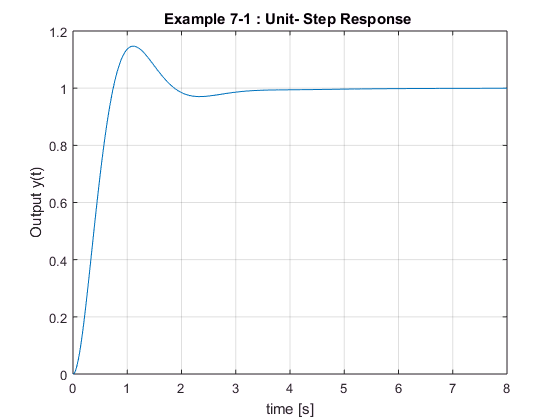

end
Solution = [K a m]

% Plot response
figure; plot(t, y), grid

title('Example 7-1 : Unit- Step Response with K = 3 and a = 1 ')
xlabel('time [s]'), ylabel('Output y(t)')

## 7-2 Case where there is no optimal solution

clear all; clc

Consider the same system from the previous example. We wish to find a combo of K and a that the max output m satisfies the condition 2.55<m<2.6 and 2<K<5 and 0.1<a<3. 

When using the previous example code, the solution to the system is K = 5, a = 3, and m = 2.9. This is simply the solution to the last search point, not the solution to the problem. If a real solution does not exist, the code would still output the last search point solution. To avoid this, you can add NaN to the end of the search regions for K and a. 

% Improve previous code for case where there is on solution
t = 0:0.01: 8; 

for K = [3:0.2:5 NaN];
    for a = [0.1:0.1:3 NaN]; 
        %Closed loop system
        num = [4*K  8*K*a  4*K*a^2];
        den = [1  6  8+4*K  4+8*K*a  4*K*a^2];
        
        %step response
        y = step(num, den, t);
        m = max(y);
        
        % Check if this combo reaches requirements
        if m<2.60 & m>2.55;
            break; %Breaks the inner loop
        end
    end
    if m<2.60 & m>2.55;
        break; %Breaks the outer loop
    end

Solution =    NaN   NaN   NaN


end
Solution = [K a m]


## 7-3 Find all solutions for the K and a combo

clear all; clc

For any particular problem, there may be more than one set of parameters that satisfy the specifications. For the same system as above, find all combinations of K and a. 

t = 0 : 0.01 : 8;
K = 3 : 0.2 : 5;
a = 0.1: 0.1: 3;

k=0;
for i = 1:11;
    for j = 1:30;
        %Closed loop system
        num = [4*K(i)  8*K(i)*a(j)  4*K(i)*a(j)^2];
        den = [1  6  8+4*K(i)  4+8*K(i)*a(j)  4*K(i)*a(j)^2];
        
        y = step(num, den, t);
        m = max(y);
        if m<1.20 & m>1.10;
            k = k+1;
            solution(k,:) = [K(i) a(j) m];
        end
    end
end

% Plot the response with the overshoot closest to 15%

sortsolution =     4.0000    0.8000    1.1003
    5.0000    0.7000    1.1019
    3.2000    0.9000    1.1065
    4.2000    0.8000    1.1107
    3.4000    0.9000    1.1181
    4.4000    0.8000    1.1208
    3.6000    0.9000    1.1291
    4.6000    0.8000    1.1304
    4.8000    0.8000    1.1396
    3.8000    0.9000    1.1396


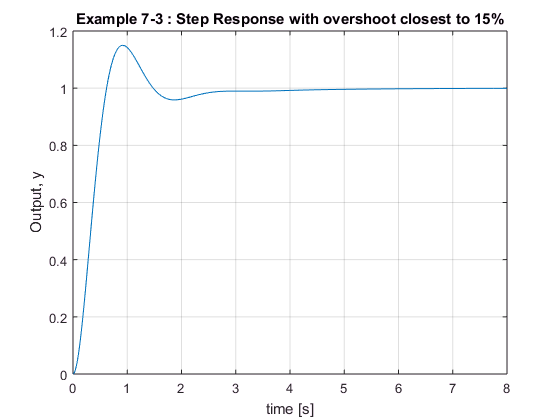

sortsolution = sortrows(solution, 3)
K = sortsolution(13,1);
a = sortsolution(13,2);

num2 = [4*K  8*K*a  4*K*a^2];
den2 = [1  6  8+4*K  4+8*K*a  4*K*a^2];

y2 = step(num2, den2, t);
figure; plot(t, y2), grid
title('Example 7-3 : Step Response with overshoot closest to 15%')

xlabel('time [s]'), ylabel('Output, y')


## 7-4 Obtain all sets of K and a to satify the criteria

clear all; clc

Criteria : the max overshoot in the unit-step response be less than 10% (include overdamped systems). Assume the search region to be 2<K<3 and 0.5<a<1.5. 

K = 2:0.2:3;
a = 0.5:0.2:1.5;

% Evaluate closed-loop unit-step response

t = 0: 0.01: 5;
g = tf([1.2], [0.36, 1.86, 2.5, 1]);
k = 0;

for i = 1:6;
    for j = 1:6;
        gc = tf(K(i)*[1 2*a(j) a(j)^2], [1 0]);
        %closed loop sys
        G = (gc*g) / (1 + gc*g);
        
        y = step(G, t);
        m = max(y);
        
        if m<1.10
            k=k+1;
            solution(k,:) = [K(i) a(j) m];
        end
    end
end

% Plot response with largest overshoot less than 10%
sortsolution = sortrows(solution, 3) %puts third row in order

sortsolution =     2.0000    0.5000    0.9002
    2.2000    0.5000    0.9114
    2.4000    0.5000    0.9207
    2.6000    0.5000    0.9283
    2.8000    0.5000    0.9348
    3.0000    0.5000    0.9402
    2.0000    0.7000    0.9807
    2.2000    0.7000    0.9837
    2.4000    0.7000    0.9859
    2.6000    0.7000    0.9877


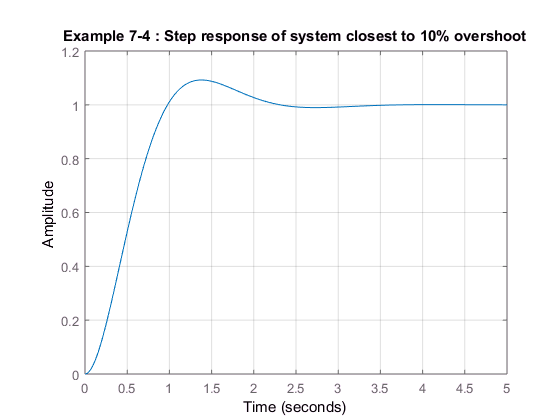

K3 = sortsolution(15,1);
a3 = sortsolution(15,2);

gc1 = tf(K3*[1 2*a3 a3^2], [1 0]);
G1 = gc1*g/(1+gc1*g);
figure; step(G1,t), grid
title('Example 7-4 : Step response of system closest to 10% overshoot')

## 7-5 Find all sets of K and a for Max overshoot <15% but >10%

clear all; clc

In addition, the settling time should be less than 3 sec and the search regions are 3<K<5 and 0.1<a<3. 

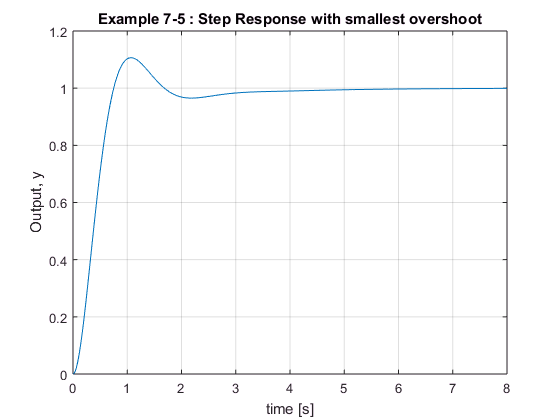

t = 0 : 0.01 : 8;

k=0;
for K = 3 : 0.2 : 5;
    for a = 0.1: 0.1: 3;
        %Closed loop system
        num = [4*K  8*K*a  4*K*a^2];
        den = [1  6  8+4*K  4+8*K*a  4*K*a^2];
        
        y = step(num, den, t);
        s = 801;
        while y(s) > 0.98 & y(s) < 1.02;
            s = s-1;
        end
        ts = (s-1) * 0.01; %settling time
        m = max(y);
        if m < 1.15 & m > 1.10;
            if ts < 3.0;
                k = k+1;
                solution(k,:) = [K a m ts];
            end
        end
    end
end

% Plot the response with the smallest overshoot 
sortsolution = sortrows(solution, 3);
K = sortsolution(1,1);
a = sortsolution(1,2);

num2 = [4*K  8*K*a  4*K*a^2];
den2 = [1  6  8+4*K  4+8*K*a  4*K*a^2];

y2 = step(num2, den2, t);
figure; plot(t, y2), grid
title('Example 7-5 : Step Response with smallest overshoot')
xlabel('time [s]'), ylabel('Output, y')